# Compare HDR versus Burst

experiment with various HDR and other multi-image "burst" algorithms for capturing scenes with a variety of dynamic ranges, as well as object and camera motion.

## Create a pbrt scene we can use

Using pbrt lets us get the highest-fidelity rendering

ieInit();
sceneLuminance = 200

sceneLuminance =    200


numRays = 256

numRays =    256


filmResolution = 256

filmResolution =    256


pbrtLensFile = false

pbrtLensFile = logical
   0


sceneChoice = "CornellBoxReference"

sceneChoice = "CornellBoxReference"

apertureDiameter = 6% in mm

apertureDiameter =      6


if strcmp(sceneChoice, "Cornell Box with Bunny")
    scenePath = 'Cornell_BoxBunnyChart';        
    sceneName = 'cornell box bunny chart';
elseif strcmp(sceneChoice, "CornellBoxReference")
    scenePath = "CornellBoxReference";
    sceneName = "CornellBoxReference";
else
    scenePath = 'ChessSet';
    sceneName = 'chessSet';
end

if pbrtLensFile
    pbrtCPScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, 'sceneLuminance', sceneLuminance, ...
    'lensFile','dgauss.22deg.6.0mm.json',...
    'apertureDiameter', apertureDiameter);
else
    pbrtCPScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, 'sceneLuminance', sceneLuminance);
end

Read 9 materials
Reading C4D geometry information.


## Create our sample camera

Just one module

% some timing code, just to see how fast we run...
setpref('ISET', 'benchmarkstart', cputime); 
setpref('ISET', 'tStart', tic);

% cpBurstCamera is a sub-class of cpCamera that implements simple HDR and Burst
% capture and processing
ourCamera = cpBurstCamera(); 

% We'll use a pre-defined sensor for our Camera Module, and let it use
% default optics for now. We can then assign the module to our camera:
sensor = sensorFromFile('ar0132atSensorRGB'); 
% Cameras can eventually have more than one module (lens + sensor)
% but for now, we just create one using our sensor
ourCamera.cmodules(1) = cpCModule('sensor', sensor); % default

## Let's Look at the Camera we've Created

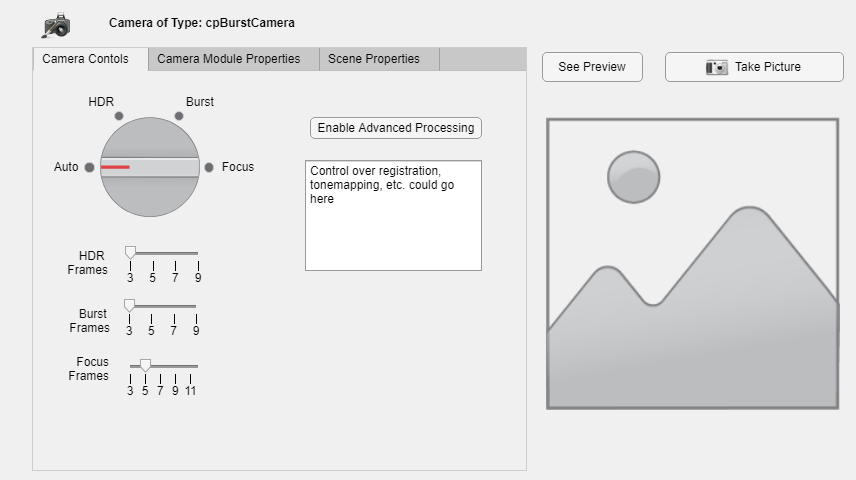

cpCameraWindow(ourCamera, pbrtCPScene);

## Take Pictures using Auto, HDR, and Burst Intents

For the simplest case we ask our camera to take some pictures using pre-defined intents. By deault our camera assumes the 'Auto' intent. We also demonstrate 'Burst', which will capture more frames if the camera type we are using supports it. 'HDR' also fires a burst, but bracketed. Our default camera sums the frames in Burst mode, and chooses the highest non-saturated value at each pixel for HDR mode.

New light added.
Creating output folder B:\iset\iset3d\local\CornellBoxReference\tp8ba5c9e1_86fe_4ce0_add5_00f2e1af4014
Copied resources from:
B:\iset\iset3d\data\V3\CornellBoxReference 
to 
B:\iset\iset3d\local\CornellBoxReference\tp8ba5c9e1_86fe_4ce0_add5_00f2e1af4014 
 
Material file CornellBoxReference_materials.pbrt written successfully.
B:\iset\iset3d\local\CornellBoxReference\tp8ba5c9e1_86fe_4ce0_add5_00f2e1af4014\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
B:\iset\iset3d\local\CornellBoxReference\tp8ba5c9e1_86fe_4ce0_add5_00f2e1af4014\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tp8ba5c9e1_86fe_4ce0_add5_00f2e1af4014 -v B:/iset/iset3d/local/CornellBoxReference/tp8ba5c9e1_86fe_4ce0_add5_00f2e1af4014:/tp8ba5c9e1_86fe_4ce0_add5_00f2e1af4014 vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: 200.000000"

New light added.
Creating output folder B:\iset\iset3d\local\CornellBoxReference\tpe6ccf856_ff60_4321_bf2c_4f1f85a6e223
Copied resources from:
B:\iset\iset3d\data\V3\CornellBoxReference 
to 
B:\iset\iset3d\local\CornellBoxReference\tpe6ccf856_ff60_4321_bf2c_4f1f85a6e223 
 
Material file CornellBoxReference_materials.pbrt written successfully.
B:\iset\iset3d\local\CornellBoxReference\tpe6ccf856_ff60_4321_bf2c_4f1f85a6e223\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
B:\iset\iset3d\local\CornellBoxReference\tpe6ccf856_ff60_4321_bf2c_4f1f85a6e223\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tpe6ccf856_ff60_4321_bf2c_4f1f85a6e223 -v B:/iset/iset3d/local/CornellBoxReference/tpe6ccf856_ff60_4321_bf2c_4f1f85a6e223:/tpe6ccf856_ff60_4321_bf2c_4f1f85a6e223 vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: 200.000000"

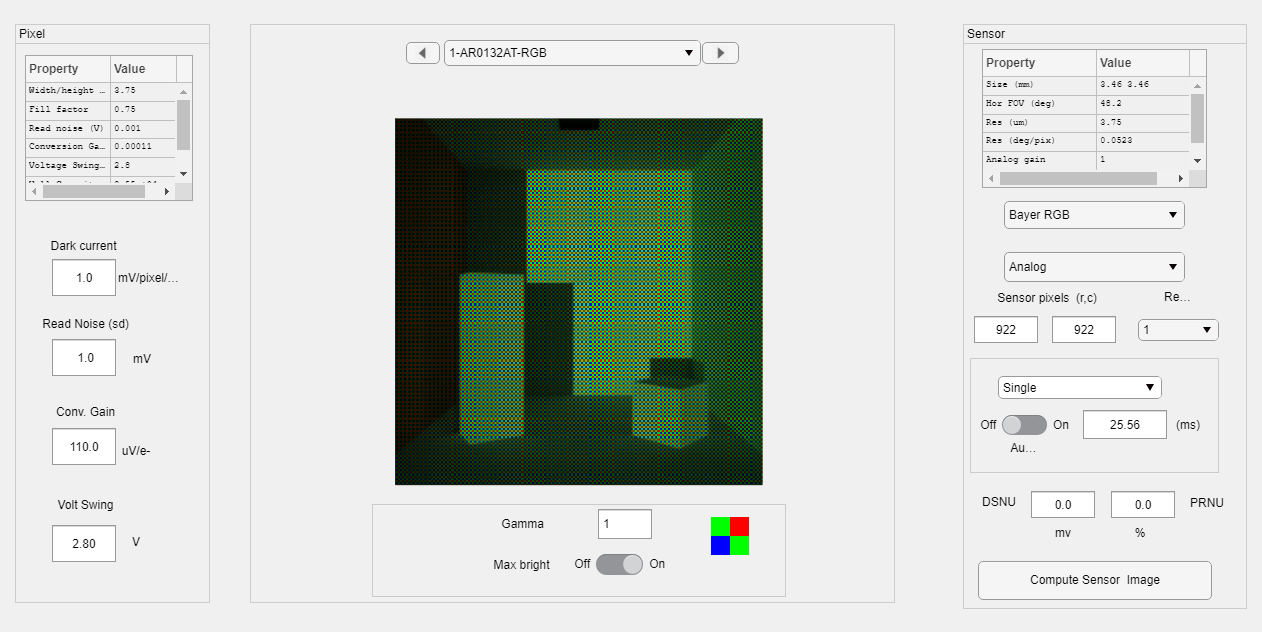

autoImage = ourCamera.TakePicture(pbrtCPScene, 'Auto',...
    'imageName','Auto Mode no motion', 'insensorIP',false); 

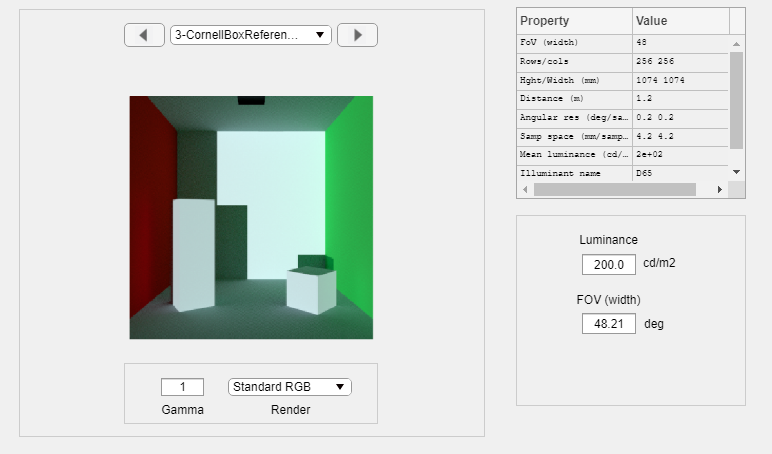

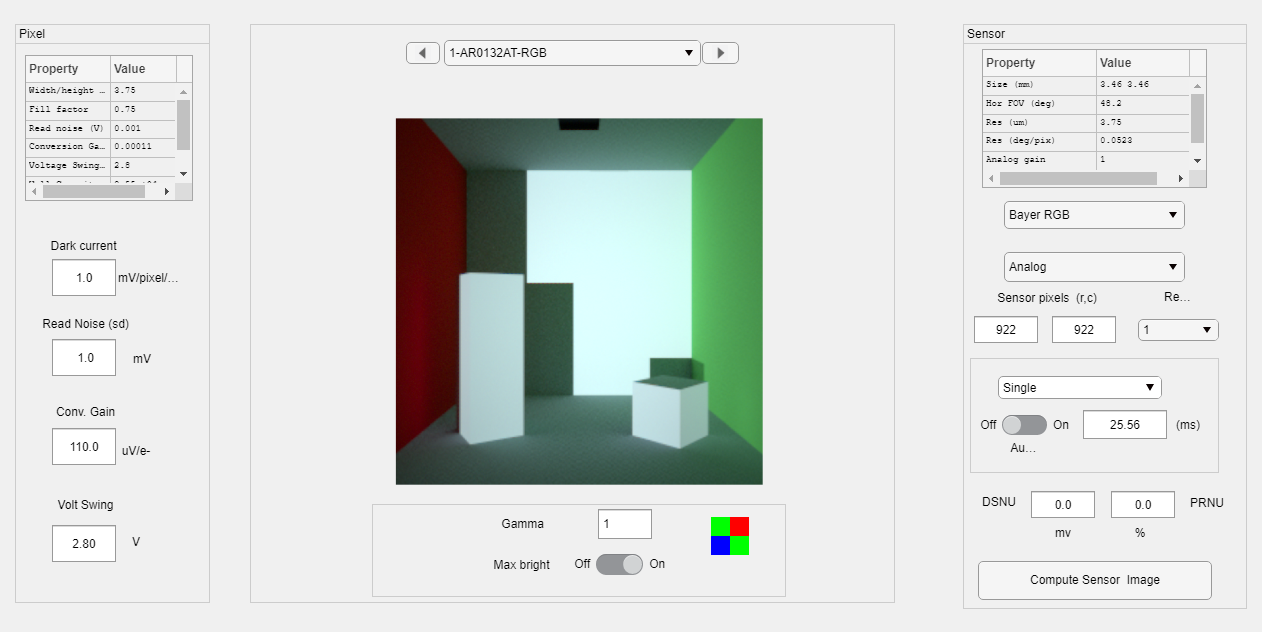

New light added.
Creating output folder B:\iset\iset3d\local\CornellBoxReference\tpe257a153_7038_4efa_ba13_0530ff35a7d5
Copied resources from:
B:\iset\iset3d\data\V3\CornellBoxReference 
to 
B:\iset\iset3d\local\CornellBoxReference\tpe257a153_7038_4efa_ba13_0530ff35a7d5 
 
Material file CornellBoxReference_materials.pbrt written successfully.
B:\iset\iset3d\local\CornellBoxReference\tpe257a153_7038_4efa_ba13_0530ff35a7d5\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
B:\iset\iset3d\local\CornellBoxReference\tpe257a153_7038_4efa_ba13_0530ff35a7d5\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tpe257a153_7038_4efa_ba13_0530ff35a7d5 -v B:/iset/iset3d/local/CornellBoxReference/tpe257a153_7038_4efa_ba13_0530ff35a7d5:/tpe257a153_7038_4efa_ba13_0530ff35a7d5 vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: 200.000000"

New light added.
Creating output folder B:\iset\iset3d\local\CornellBoxReference\tpc66c16d3_7036_4ba6_95ca_1b5e9f41875e
Copied resources from:
B:\iset\iset3d\data\V3\CornellBoxReference 
to 
B:\iset\iset3d\local\CornellBoxReference\tpc66c16d3_7036_4ba6_95ca_1b5e9f41875e 
 
Material file CornellBoxReference_materials.pbrt written successfully.
B:\iset\iset3d\local\CornellBoxReference\tpc66c16d3_7036_4ba6_95ca_1b5e9f41875e\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
B:\iset\iset3d\local\CornellBoxReference\tpc66c16d3_7036_4ba6_95ca_1b5e9f41875e\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tpc66c16d3_7036_4ba6_95ca_1b5e9f41875e -v B:/iset/iset3d/local/CornellBoxReference/tpc66c16d3_7036_4ba6_95ca_1b5e9f41875e:/tpc66c16d3_7036_4ba6_95ca_1b5e9f41875e vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: 200.000000"

Creating output folder B:\iset\iset3d\local\CornellBoxReference\tp20711fa7_5b24_4271_8d08_3574f47a2676
Copied resources from:
B:\iset\iset3d\data\V3\CornellBoxReference 
to 
B:\iset\iset3d\local\CornellBoxReference\tp20711fa7_5b24_4271_8d08_3574f47a2676 
 
Material file CornellBoxReference_materials.pbrt written successfully.
B:\iset\iset3d\local\CornellBoxReference\tp20711fa7_5b24_4271_8d08_3574f47a2676\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
B:\iset\iset3d\local\CornellBoxReference\tp20711fa7_5b24_4271_8d08_3574f47a2676\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tp20711fa7_5b24_4271_8d08_3574f47a2676 -v B:/iset/iset3d/local/CornellBoxReference/tp20711fa7_5b24_4271_8d08_3574f47a2676:/tp20711fa7_5b24_4271_8d08_3574f47a2676 vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReferenc

ans = "Scene luminance is: 200.000000"

Creating output folder B:\iset\iset3d\local\CornellBoxReference\tpd14ad64d_b822_4a21_b8dd_1c0df0f7a85e
Copied resources from:
B:\iset\iset3d\data\V3\CornellBoxReference 
to 
B:\iset\iset3d\local\CornellBoxReference\tpd14ad64d_b822_4a21_b8dd_1c0df0f7a85e 
 
Material file CornellBoxReference_materials.pbrt written successfully.
B:\iset\iset3d\local\CornellBoxReference\tpd14ad64d_b822_4a21_b8dd_1c0df0f7a85e\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
B:\iset\iset3d\local\CornellBoxReference\tpd14ad64d_b822_4a21_b8dd_1c0df0f7a85e\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tpd14ad64d_b822_4a21_b8dd_1c0df0f7a85e -v B:/iset/iset3d/local/CornellBoxReference/tpd14ad64d_b822_4a21_b8dd_1c0df0f7a85e:/tpd14ad64d_b822_4a21_b8dd_1c0df0f7a85e vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReferenc

ans = "Scene luminance is: 200.000000"

imshow(autoImage);

hdrImage = ourCamera.TakePicture(pbrtCPScene, 'HDR',...
    'numHDRFrames', 3,'imageName','HDR in sensor no motion', ...
    'insensorIP', true);

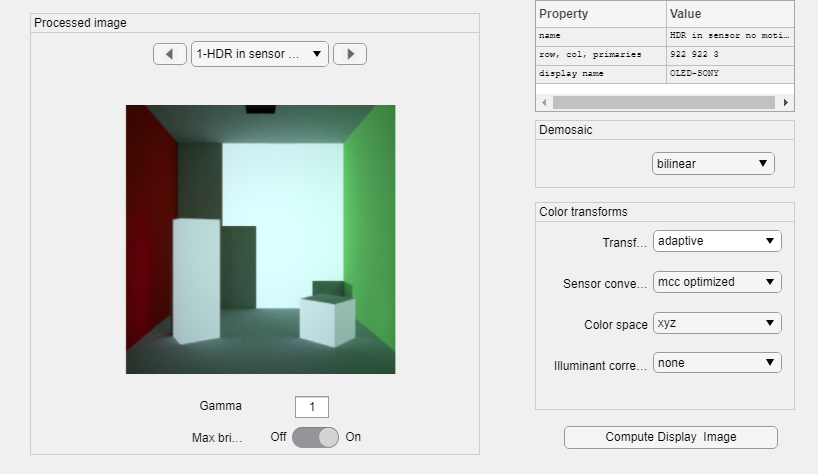

ipWindow(hdrImage);

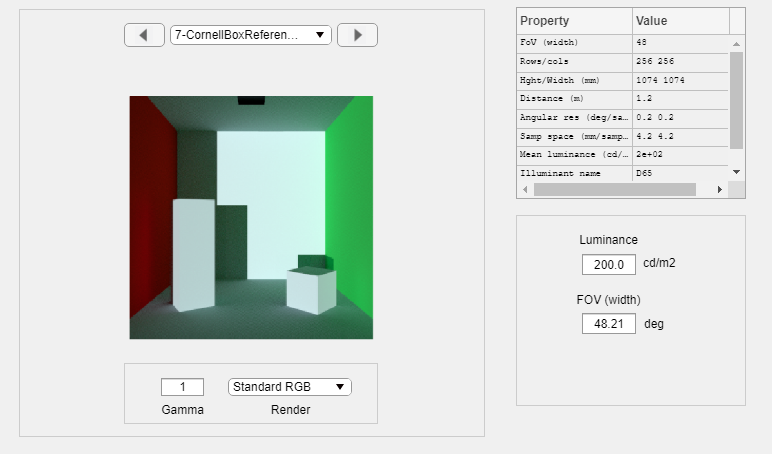

New light added.
Creating output folder B:\iset\iset3d\local\CornellBoxReference\tp98042403_ffd5_4f2a_8cbe_5fd0f624226b
Copied resources from:
B:\iset\iset3d\data\V3\CornellBoxReference 
to 
B:\iset\iset3d\local\CornellBoxReference\tp98042403_ffd5_4f2a_8cbe_5fd0f624226b 
 
Material file CornellBoxReference_materials.pbrt written successfully.
B:\iset\iset3d\local\CornellBoxReference\tp98042403_ffd5_4f2a_8cbe_5fd0f624226b\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
B:\iset\iset3d\local\CornellBoxReference\tp98042403_ffd5_4f2a_8cbe_5fd0f624226b\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tp98042403_ffd5_4f2a_8cbe_5fd0f624226b -v B:/iset/iset3d/local/CornellBoxReference/tp98042403_ffd5_4f2a_8cbe_5fd0f624226b:/tp98042403_ffd5_4f2a_8cbe_5fd0f624226b vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: 200.000000"

New light added.
Creating output folder B:\iset\iset3d\local\CornellBoxReference\tpdbd4682d_f03e_488f_9af0_8b0cb01846e9
Copied resources from:
B:\iset\iset3d\data\V3\CornellBoxReference 
to 
B:\iset\iset3d\local\CornellBoxReference\tpdbd4682d_f03e_488f_9af0_8b0cb01846e9 
 
Material file CornellBoxReference_materials.pbrt written successfully.
B:\iset\iset3d\local\CornellBoxReference\tpdbd4682d_f03e_488f_9af0_8b0cb01846e9\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
B:\iset\iset3d\local\CornellBoxReference\tpdbd4682d_f03e_488f_9af0_8b0cb01846e9\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tpdbd4682d_f03e_488f_9af0_8b0cb01846e9 -v B:/iset/iset3d/local/CornellBoxReference/tpdbd4682d_f03e_488f_9af0_8b0cb01846e9:/tpdbd4682d_f03e_488f_9af0_8b0cb01846e9 vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: 200.000000"

Creating output folder B:\iset\iset3d\local\CornellBoxReference\tpc19defbc_0542_4976_bbe9_f6c650a63b9d
Copied resources from:
B:\iset\iset3d\data\V3\CornellBoxReference 
to 
B:\iset\iset3d\local\CornellBoxReference\tpc19defbc_0542_4976_bbe9_f6c650a63b9d 
 
Material file CornellBoxReference_materials.pbrt written successfully.
B:\iset\iset3d\local\CornellBoxReference\tpc19defbc_0542_4976_bbe9_f6c650a63b9d\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
B:\iset\iset3d\local\CornellBoxReference\tpc19defbc_0542_4976_bbe9_f6c650a63b9d\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tpc19defbc_0542_4976_bbe9_f6c650a63b9d -v B:/iset/iset3d/local/CornellBoxReference/tpc19defbc_0542_4976_bbe9_f6c650a63b9d:/tpc19defbc_0542_4976_bbe9_f6c650a63b9d vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReferenc

ans = "Scene luminance is: 200.000000"

Creating output folder B:\iset\iset3d\local\CornellBoxReference\tp527892e2_e4e4_46e5_8602_5b0759c3e00b
Copied resources from:
B:\iset\iset3d\data\V3\CornellBoxReference 
to 
B:\iset\iset3d\local\CornellBoxReference\tp527892e2_e4e4_46e5_8602_5b0759c3e00b 
 
Material file CornellBoxReference_materials.pbrt written successfully.
B:\iset\iset3d\local\CornellBoxReference\tp527892e2_e4e4_46e5_8602_5b0759c3e00b\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
B:\iset\iset3d\local\CornellBoxReference\tp527892e2_e4e4_46e5_8602_5b0759c3e00b\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tp527892e2_e4e4_46e5_8602_5b0759c3e00b -v B:/iset/iset3d/local/CornellBoxReference/tp527892e2_e4e4_46e5_8602_5b0759c3e00b:/tp527892e2_e4e4_46e5_8602_5b0759c3e00b vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReferenc

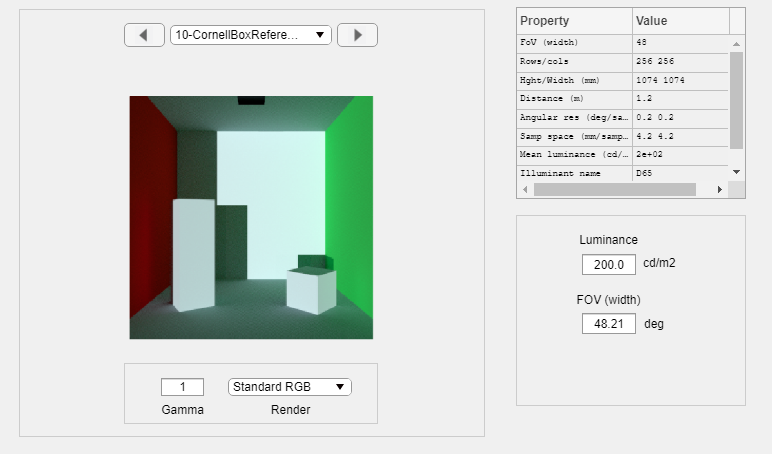

ans = "Scene luminance is: 200.000000"


hdrImage = ourCamera.TakePicture(pbrtCPScene, 'HDR',...
    'numHDRFrames', 3,'imageName','HDR in sensor', ...
    'insensorIP', false);

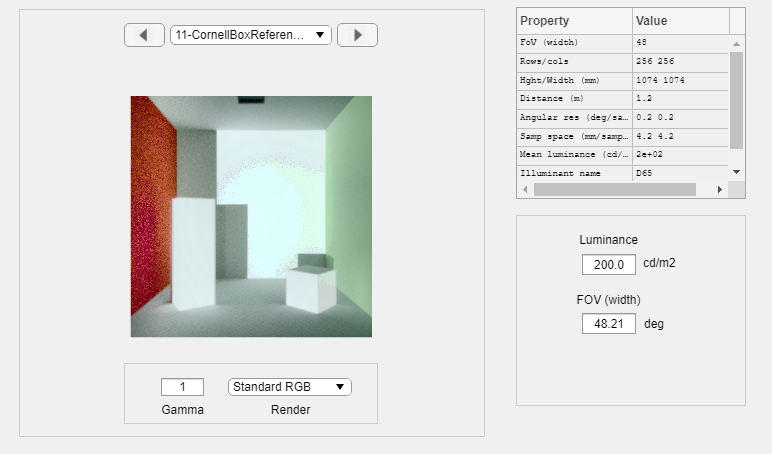

New light added.
Creating output folder B:\iset\iset3d\local\CornellBoxReference\tp993548c4_4dde_4b68_9ca9_642ead37723f
Copied resources from:
B:\iset\iset3d\data\V3\CornellBoxReference 
to 
B:\iset\iset3d\local\CornellBoxReference\tp993548c4_4dde_4b68_9ca9_642ead37723f 
 
Material file CornellBoxReference_materials.pbrt written successfully.
B:\iset\iset3d\local\CornellBoxReference\tp993548c4_4dde_4b68_9ca9_642ead37723f\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
B:\iset\iset3d\local\CornellBoxReference\tp993548c4_4dde_4b68_9ca9_642ead37723f\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tp993548c4_4dde_4b68_9ca9_642ead37723f -v B:/iset/iset3d/local/CornellBoxReference/tp993548c4_4dde_4b68_9ca9_642ead37723f:/tp993548c4_4dde_4b68_9ca9_642ead37723f vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: 200.000000"

New light added.
Creating output folder B:\iset\iset3d\local\CornellBoxReference\tp6aa248c2_eaba_49d4_a32e_870522b52168
Copied resources from:
B:\iset\iset3d\data\V3\CornellBoxReference 
to 
B:\iset\iset3d\local\CornellBoxReference\tp6aa248c2_eaba_49d4_a32e_870522b52168 
 
Material file CornellBoxReference_materials.pbrt written successfully.
B:\iset\iset3d\local\CornellBoxReference\tp6aa248c2_eaba_49d4_a32e_870522b52168\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
B:\iset\iset3d\local\CornellBoxReference\tp6aa248c2_eaba_49d4_a32e_870522b52168\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tp6aa248c2_eaba_49d4_a32e_870522b52168 -v B:/iset/iset3d/local/CornellBoxReference/tp6aa248c2_eaba_49d4_a32e_870522b52168:/tp6aa248c2_eaba_49d4_a32e_870522b52168 vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: 200.000000"

Creating output folder B:\iset\iset3d\local\CornellBoxReference\tp895d7aed_9a8a_4720_9331_ff857d35258f
Copied resources from:
B:\iset\iset3d\data\V3\CornellBoxReference 
to 
B:\iset\iset3d\local\CornellBoxReference\tp895d7aed_9a8a_4720_9331_ff857d35258f 
 
Material file CornellBoxReference_materials.pbrt written successfully.
B:\iset\iset3d\local\CornellBoxReference\tp895d7aed_9a8a_4720_9331_ff857d35258f\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
B:\iset\iset3d\local\CornellBoxReference\tp895d7aed_9a8a_4720_9331_ff857d35258f\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tp895d7aed_9a8a_4720_9331_ff857d35258f -v B:/iset/iset3d/local/CornellBoxReference/tp895d7aed_9a8a_4720_9331_ff857d35258f:/tp895d7aed_9a8a_4720_9331_ff857d35258f vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReferenc

ans = "Scene luminance is: 200.000000"

Creating output folder B:\iset\iset3d\local\CornellBoxReference\tpb450dba3_e9c1_45a5_9849_ded7a80e923d
Copied resources from:
B:\iset\iset3d\data\V3\CornellBoxReference 
to 
B:\iset\iset3d\local\CornellBoxReference\tpb450dba3_e9c1_45a5_9849_ded7a80e923d 
 
Material file CornellBoxReference_materials.pbrt written successfully.
B:\iset\iset3d\local\CornellBoxReference\tpb450dba3_e9c1_45a5_9849_ded7a80e923d\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
B:\iset\iset3d\local\CornellBoxReference\tpb450dba3_e9c1_45a5_9849_ded7a80e923d\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tpb450dba3_e9c1_45a5_9849_ded7a80e923d -v B:/iset/iset3d/local/CornellBoxReference/tpb450dba3_e9c1_45a5_9849_ded7a80e923d:/tpb450dba3_e9c1_45a5_9849_ded7a80e923d vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReferenc

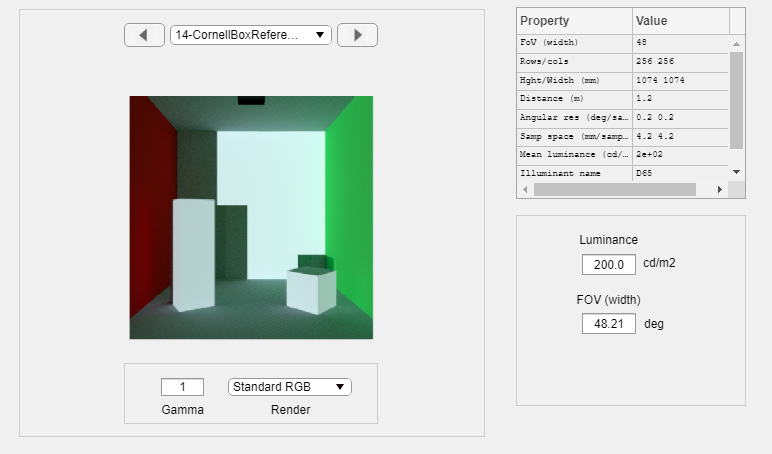

ans = "Scene luminance is: 200.000000"

imshow(hdrImage);

burstImage = ourCamera.TakePicture(pbrtCPScene, 'Burst',...
    'numBurstFrames', 3, 'imageName','Burst in ISP',...
    'insensorIP',false);

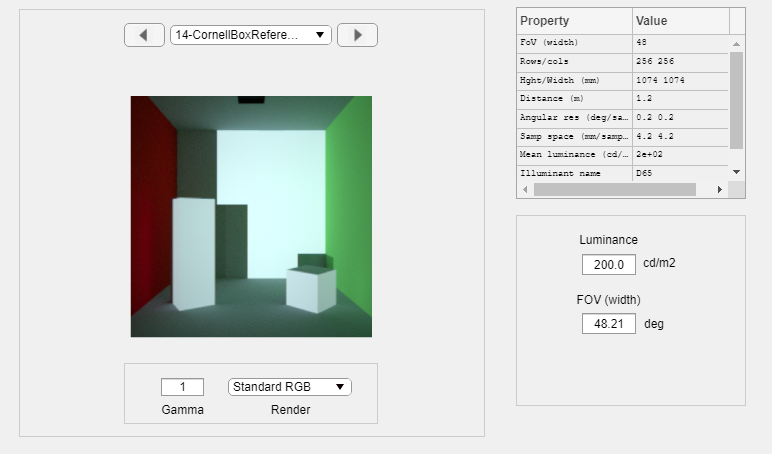

imshow(burstImage);